## Init

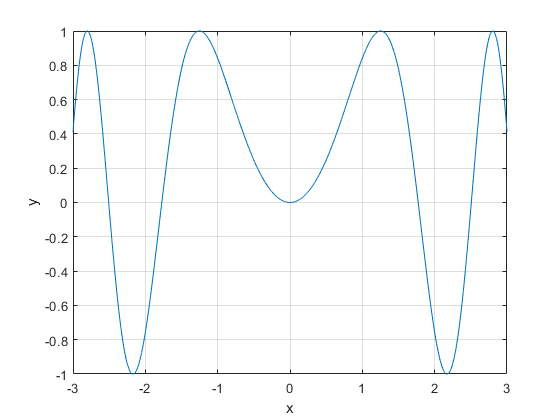

x=-3:0.001:3;
figure
plot(x,objectiveFcn(x)); grid on;
xlabel('x');ylabel('y');

## Optimizer - Genetic Algorithm

nrVar=1;


Diagnostic information:
Fitness function: @objectiveFcn
1 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
PopulationSize:    50
Generations:       25
Display:           'diagnose'
PlotFcns:          {  'gaplotscores' 'gaplotbestf' }
OutputFcns:        @outputFcnTest
End of diagnostic information.

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100              -1        -0.05924        0
    2              147              -1         -0.2563        1
    3              194              -1         -0.2553        2
    4              241              -1         -0.4756        3
    5              288              -1            -0.8        4
    6              335              -1         -0.8983        5
    7              382              -1         -0.

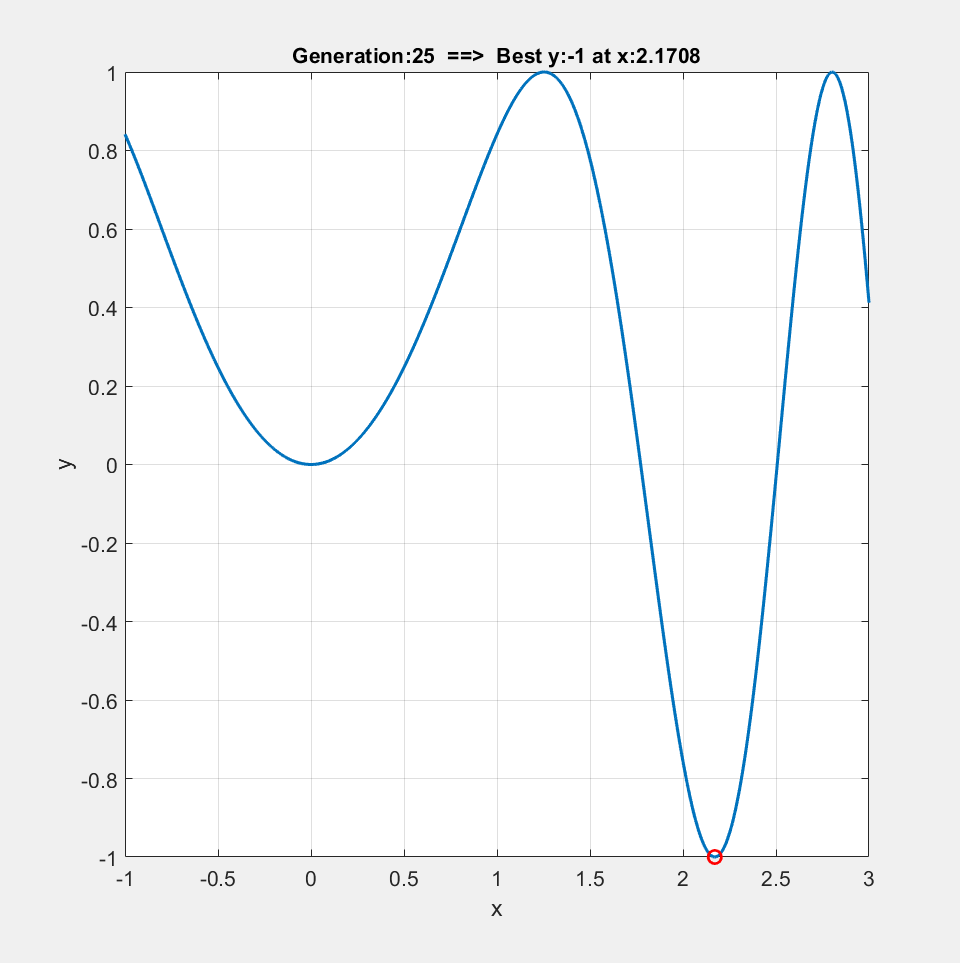

   25             1228              -1              -1        2
Optimization terminated: maximum number of generations exceeded.


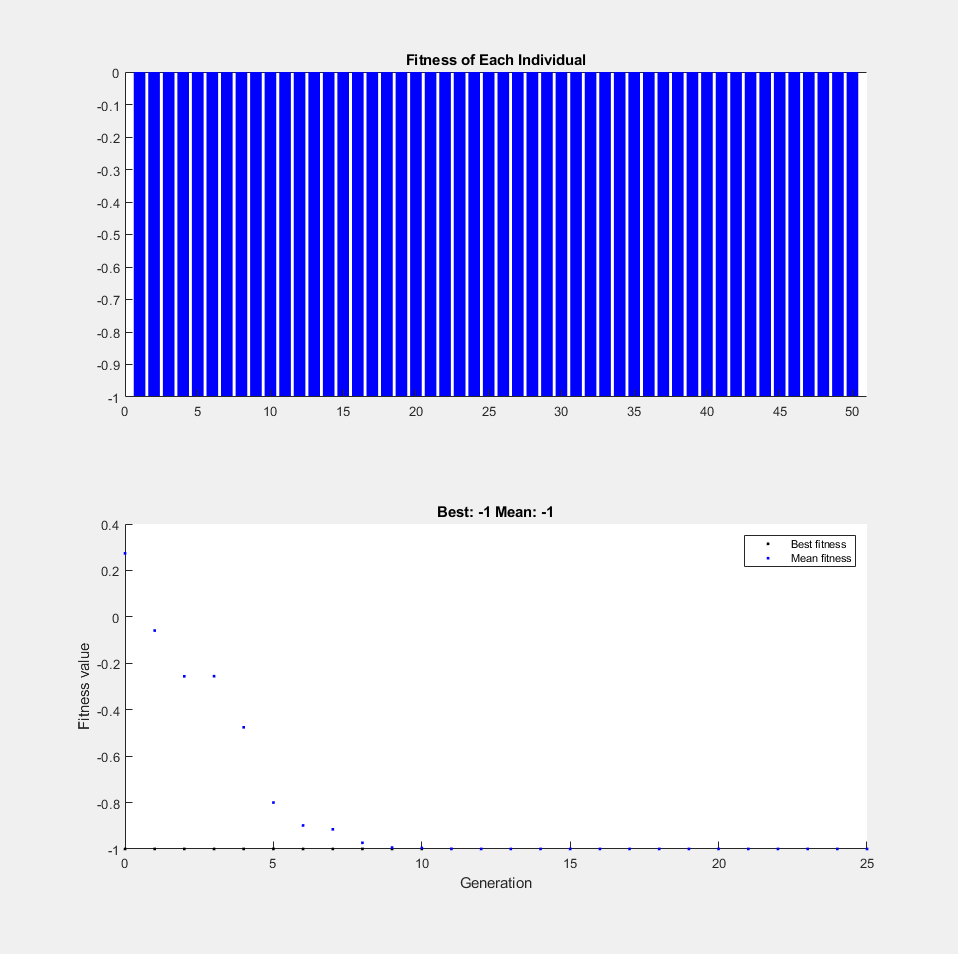

% Set nondefault solver options
options4 = optimoptions("ga","OutputFcn",[@outputFcnTest],"MaxGenerations",25,...
    "PopulationSize",50,"Display","diagnose","PlotFcn",["gaplotscores",...
    "gaplotbestf"]);

% Solve
[solution,objectiveValue] = ga(@objectiveFcn,nrVar,[],[],[],[],repmat(-1,...
    nrVar,1),repmat(3,nrVar,1),[],[],options4);


% Clear variables
clearvars options4

## Objective function

function f = objectiveFcn(optimInput)
f = sin(optimInput.^2);
end

## Help functions

function [state,options,optchanged] = outputFcnTest(options,state,flag)
optchanged = false;

switch flag

    case 'init'

        fontSize = 16;

        % Plot init
        state.fig=figure;
        state.fig.WindowState = 'maximized';%set(gcf, 'Position', get(0, 'Screensize'));
        set(gcf,'Visible','on'); % to make it visible outside the live editor
        x=-1:0.01:3;
        for ii=1:numel(x)
            y(ii)=objectiveFcn(x(ii));
        end
        state.ax=subplot(1,1,1);
        plot(x,y,'LineWidth',2); grid on; xlabel('x','FontSize', fontSize);ylabel('y','FontSize', fontSize);
        set(gca,'FontSize',fontSize)
        title('Find the global minimun of the function sin(x^2), x=[-1 3]','FontSize', fontSize);

        %test;

    case 'iter'

        % Get top n values
        [~,indTop]      = sort(state.Score);
        topScore        = state.Score(indTop);
        topPopulation   = state.Population(indTop);

        n               = 1;
        topScore        = topScore(1:n);
        topPopulation   = topPopulation(1:n);

        % Plot iter
        try
            hold(state.ax,'on');
            delete(state.p);
        end
        state.p=plot(state.ax,state.Population,state.Score,'or','MarkerSize',10,'LineWidth',2);
        title(state.ax,['Generation:' num2str(state.Generation) '  ==>  Best y:' num2str(topScore(1))  ' at x:' num2str(topPopulation(1))]);
        pause(2);

    case 'done'

end
end
